# 3-D Brain Tumor Segmentation Using Deep Learning

This example shows how to perform semantic segmentation of brain tumors from 3-D medical images.

Semantic segmentation involves labeling each pixel in an image or voxel of a 3-D volume with a class. This example uses a 3-D U-Net deep learning network to perform binary semantic segmentation of brain tumors in magnetic resonance imaging (MRI) scans. U-Net is a fast, efficient, and simple network that has become popular in the semantic segmentation domain [1].

One challenge of medical image segmentation is the amount of memory needed to store and process 3-D volumes. Training a network and performing segmentation on the full input volume is impractical due to GPU resource constraints. This example solves the problem by dividing the image into smaller patches, or blocks, for training and segmentation.

A second challenge of medical image segmentation is class imbalance in the data that hampers training when using conventional cross entropy loss. This example solves the problem by using a weighted multiclass Dice loss function [4]. Weighting the classes helps counter the influence of larger regions on the Dice score, making it easier for the network to learn how to segment smaller regions.

This example shows how to perform brain tumor segmentation using a pretrained 3-D U-Net architecture, and how to evaluate the network performance using a set of test images. You can optionally train a 3-D U-Net on the BraTS data set [2]. 

## Load Pretrained 3-D U-Net

Download a pretrained 3-D U-Net into a variable called `trainedNet`. You can use the pretrained network to run the example without waiting for training to complete.

dataDir = fullfile(tempdir,"BraTS");
if ~exist(dataDir,"dir")
    mkdir(dataDir);
end
trained3DUnetURL = "https://www.mathworks.com/supportfiles/"+ ...
    "vision/data/brainTumorSegmentation3DUnet_v2.zip";
downloadTrainedNetwork(trained3DUnetURL,dataDir);
load(fullfile(dataDir,"brainTumorSegmentation3DUnet_v2.mat"));

## Perform Semantic Segmentation

Use the pretrained network to predict the tumor labels for a test MRI volume.

### Load Sample BraTS Data

This example uses the BraTS data set [2]. The full data set contains labeled MRI scans of brain tumors from 750 patients. To try the pretrained network, download a subset of five MRI scans and their corresponding labels from the MathWorks® website. Download the sample data by using the `downloadBraTSSampleTestData` helper function [3], which is attached to the example as a supporting file.

downloadBraTSSampleTestData(dataDir);

Load one of the MRI volumes with its pixel label ground truth. Each volume is a 4-D array, where the first three dimensions correspond to the height, width, and depth of the image data, and each page of the fourth dimension contains a different MRI modality.

testDir = fullfile(dataDir,"sampleBraTSTestSetValid");
data = load(fullfile(testDir,"imagesTest","BraTS446.mat"));
labels = load(fullfile(testDir,"labelsTest","BraTS446.mat"));
volTest = data.cropVol;
volTestLabels = labels.cropLabel;

### Segment Brain Tumor in Blocked Image

To process the large volumes efficiently, this example processes each MRI scan as a series of 3-D blocks in a  [`blockedImage`](docid:images_ref#mw_284fc4ed-4502-4b5b-a71a-c6fcaf99ec77) object. Using the [`apply`](docid:images_ref#mw_d2a929bc-2fd0-45b6-b4ed-0e2671850b23) function, the network predicts the labels for each block, and then combines the blocks back into a complete segmented volume.

Create a `blockedImage` object for the downloaded sample volume.

bim = blockedImage(volTest);

The `apply` function executes a custom function for each block within the `blockedImage`. Define `semanticsegBlock` as the function to apply to each block. To predict labels for the classes in `classNames`, the `semanticsegBlock` function applies the pretrained network using the [`semanticseg`](docid:vision_ref#mw_bbecb1af-a6c9-43d1-91f5-48607edc15d1) function.

classNames = ["background","tumor"];
semanticsegBlock = @(bstruct)semanticseg(bstruct.Data,trainedNet,Classes=classNames);

When you call the `apply` function, you can specify options such as the block size and border size between blocks. Specify the block size to match the network output size. Obtain the network output size by passing a sample image of the same size as the network input to the pretrained network.

networkInputSize = trainedNet.Layers(1).InputSize;

sampleImage = rand(networkInputSize,"single");
sampleOutput = predict(trainedNet,sampleImage);

networkOutputSize = size(sampleOutput);

blockSize = [networkOutputSize(1:3) networkInputSize(end)];

To create overlapping blocks, specify a nonzero border size. This example uses a border size such that the block plus the border matches the network input size.

borderSize = (networkInputSize(1:3) - blockSize(1:3))/2;

Apply the `semanticsegBlock` function to all blocks of the test image. Specify partial block padding as `true`. The default padding method, `"replicate"`, is appropriate because the volume data contains multiple modalities. Specify the batch size as 1 to prevent out-of-memory errors on machines with constrained memory resources. However, if your machine has sufficient memory, then you can increase the processing speed by increasing the block size.

batchSize = 1;
results = apply(bim, ...
    semanticsegBlock, ...
    BlockSize=blockSize, ...
    BorderSize=borderSize, ...
    PadPartialBlocks=true, ...
    BatchSize=batchSize);
predictedLabels = gather(results);

Display a montage showing the center slices of the ground truth and predicted labels along the depth direction.

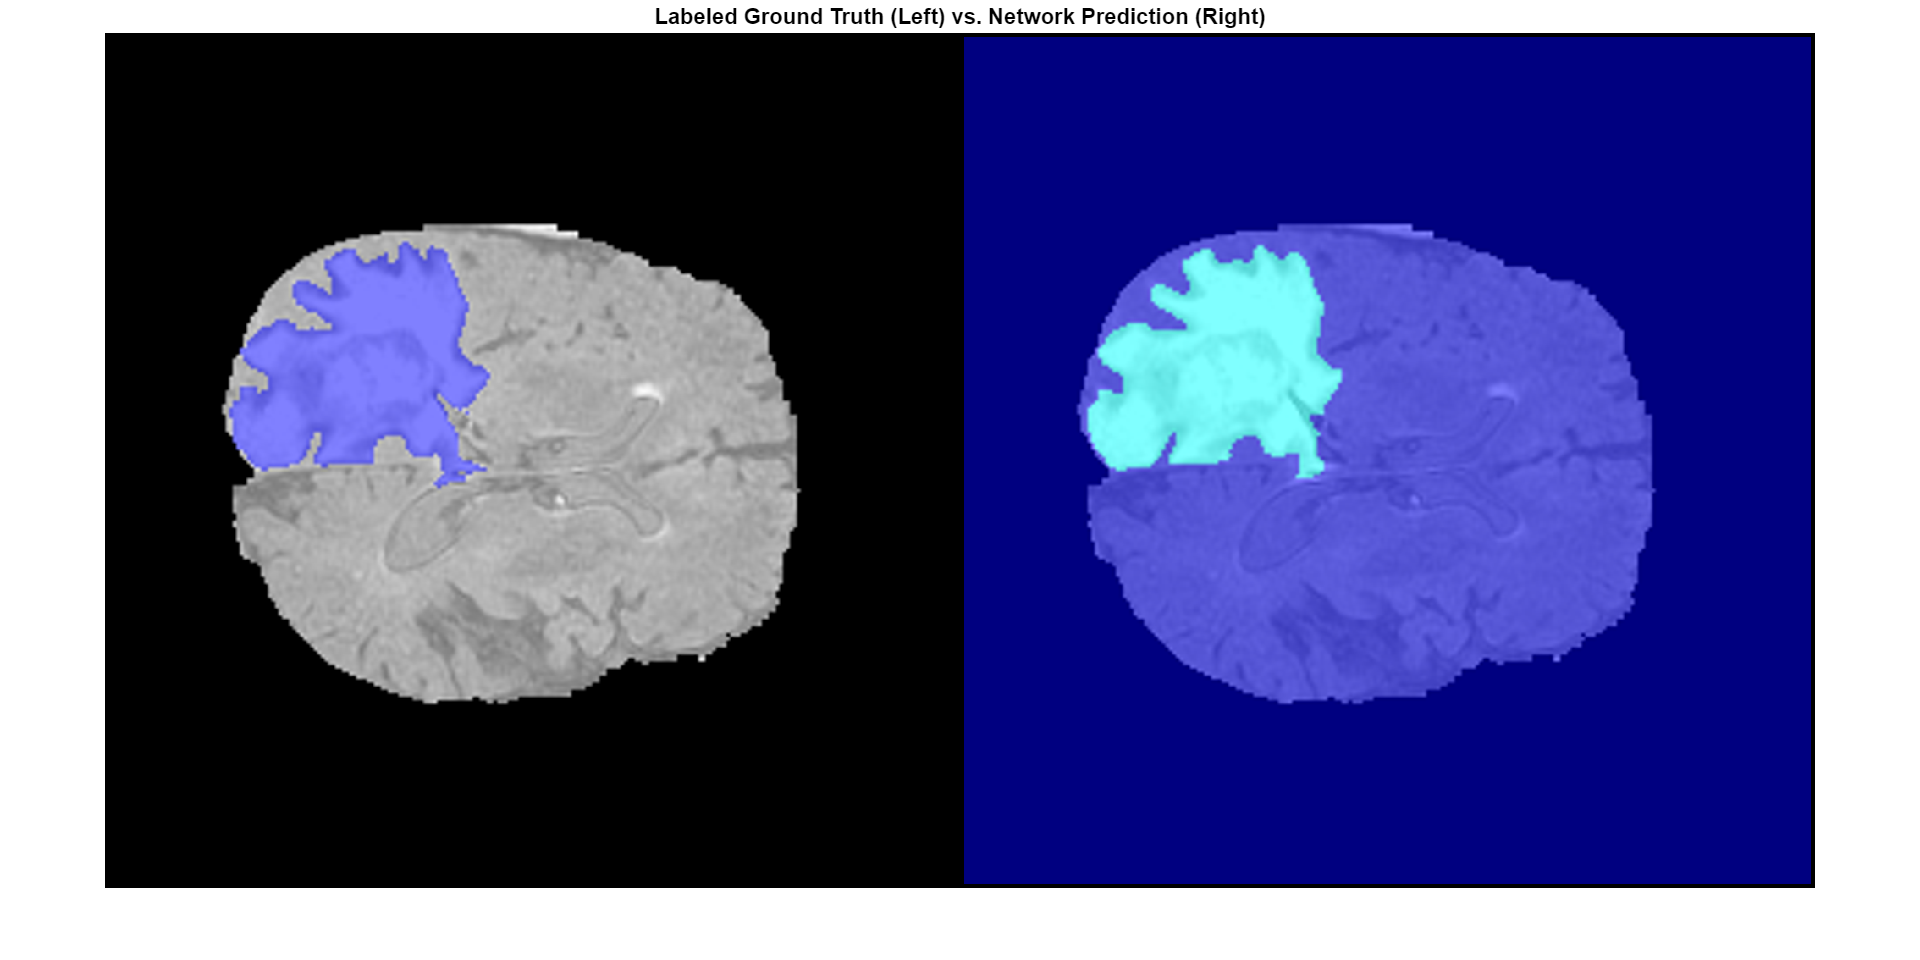

zID = size(volTest,3)/2;
zSliceGT = labeloverlay(volTest(:,:,zID),volTestLabels(:,:,zID));
zSlicePred = labeloverlay(volTest(:,:,zID),predictedLabels(:,:,zID));

figure
montage({zSliceGT,zSlicePred},Size=[1 2],BorderSize=5) 
title("Labeled Ground Truth (Left) vs. Network Prediction (Right)")

This animation shows a side-by-side view of the transverse slices of the ground truth and predicted labels for one test volume. The labeled ground truth is on the left, and the network prediction is on the right.

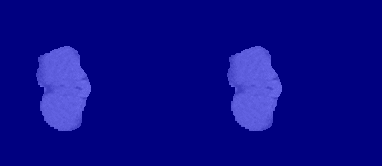

## Prepare Data for Training

### Download Full BraTS Data Set

To perform training, you must download the full BraTS data set. The total size of the data set is ~7 GB, and it contains data from 750 patients. If you do not want to download the training data set or train the network, then you can skip to the Evaluate Network Performance section of this example.

To download the BraTS data, go to the [Medical Segmentation Decathlon](http://medicaldecathlon.com/) website and click the **Download Data** link. Download the `Task01_BrainTumour.tar` file [3]. Unzip the TAR file into the directory specified by the `imageDir` variable. When unzipped successfully, `imageDir` contains a directory named `Task01_BrainTumour` that has three subdirectories: `imagesTr`, `imagesTs`, and `labelsTr`. 

Similar to the sample data set, each scan is a 4-D array where the first three dimensions correspond to the height, width, and depth of a 3-D image, and each page of the fourth dimension corresponds to a different modality. The data set is divided into 484 training volumes with voxel labels and 266 test volumes. The test volumes do not have labels, so this example does not use the test data. Instead, the example splits the 484 training volumes into three independent sets to use for training, validation, and testing.

### Preprocess Data

To train the 3-D U-Net network more efficiently, preprocess the MRI data by using the `preprocessBraTSDataset` helper function. This function is attached to the example as a supporting file. The helper function performs these operations:

- Crop the data to a region containing the brain and tumor. Cropping reduces the size of data while retaining the most critical part of each MRI volume and its corresponding labels.

- Normalize each modality of each volume independently by subtracting the mean and dividing by the standard deviation of the cropped brain region.

- Split the 484 training volumes into 400 training, 29 validation, and 55 test sets.

Preprocessing the data can take about 30 minutes to complete. 

sourceDataLoc = fullfile(dataDir,"Task01_BrainTumour");
preprocessDataLoc = fullfile(dataDir,"preprocessedDataset");
if ~isfolder(preprocessDataLoc)
    preprocessBraTSDataset(preprocessDataLoc,sourceDataLoc);
end

### Create Random Patch Extraction Datastore for Training and Validation

To read and manage the 3-D training image data, create an [`imageDatastore`](docid:matlab_ref#butueui-1) object. Specify a custom read function, `matRead`, to read the image data from MAT files. The `matRead` helper function is attached to the example as a supporting file. 

volLocTrain = fullfile(preprocessDataLoc,"imagesTr");
voldsTrain = imageDatastore(volLocTrain,FileExtensions=".mat",ReadFcn=@matRead);

To read and manage the labels, create a [`pixelLabelDatastore`](docid:vision_ref#mw_c2246553-ba4a-4bad-aad4-6ab8fa2f7f2d) object. Specify the same class names as defined for the `classNames` variable. The pixel label ID `1` maps to the `"tumor"` class name, and the pixel label ID `0` maps to the `"background"` class name.

disp(classNames)

    "background"    "tumor"



pixelLabelID = [0 1];
lblLocTrain = fullfile(preprocessDataLoc,"labelsTr");

pxdsTrain = pixelLabelDatastore(lblLocTrain,classNames,pixelLabelID, ...
    FileExtensions=".mat",ReadFcn=@matRead);

Create a [`randomPatchExtractionDatastore`](docid:images_ref#mw_19a16ac8-a068-411c-8f32-def517a4399a) object that extracts random patches from ground truth images and their corresponding pixel label data. Specify a patch size of 132-by-132-by-132 voxels. Specify the "`PatchesPerImage"` name-value argument to extract 16 randomly positioned patches from each pair of volumes and labels during training. Specify a mini-batch size of 4.

patchSize = [132 132 132];
patchPerImage = 16;
miniBatchSize = 4;
patchdsTrain = randomPatchExtractionDatastore(voldsTrain,pxdsTrain,patchSize, ...
    PatchesPerImage=patchPerImage);
patchdsTrain.MiniBatchSize = miniBatchSize;

Similarly, to manage the validation data set, create `imageDatastore`, `pixeLabelDatastore`, and `randomPatchExtractionDatastore` objects. You can use validation data to evaluate whether the network is continuously learning, underfitting, or overfitting during training.

volLocVal = fullfile(preprocessDataLoc,"imagesVal");
voldsVal = imageDatastore(volLocVal,FileExtensions=".mat", ...
    ReadFcn=@matRead);

lblLocVal = fullfile(preprocessDataLoc,"labelsVal");
pxdsVal = pixelLabelDatastore(lblLocVal,classNames,pixelLabelID, ...
    FileExtensions=".mat",ReadFcn=@matRead);

patchdsVal = randomPatchExtractionDatastore(voldsVal,pxdsVal,patchSize, ...
    PatchesPerImage=patchPerImage);
patchdsVal.MiniBatchSize = miniBatchSize;

## Define 3-D U-Net Network Architecture

This example uses the 3-D U-Net network [1]. In U-Net, the initial series of convolutional layers are interspersed with max pooling layers, successively decreasing the resolution of the input image. These layers are followed by a series of convolutional layers interspersed with upsampling operators, successively increasing the resolution of the input image. A batch normalization layer is introduced before each ReLU layer. The name U-Net comes from the fact that the network can be drawn with a symmetric shape, like the letter U.

Create a default 3-D U-Net network by using the [`unet3d`](docid:vision_ref#mw_ce5031ae-be49-4e7f-ac3a-b9d5be88fa14) function. Specify two-class segmentation. To avoid border artifacts, also specify valid convolution padding.

numChannels = 4;
inputPatchSize = [patchSize numChannels];
numClasses = 2;
[net,outPatchSize] = unet3d(inputPatchSize, ...
    numClasses,ConvolutionPadding="valid");

Augment the training and validation data by using the [`transform`](docid:matlab_ref#mw_16489124-fe7e-4381-b715-8d3b8b30a9f6) function with custom preprocessing operations specified by the `augmentAndCrop3dPatch` helper function. This function is attached to the example as a supporting file. The `augmentAndCrop3dPatch` function performs these operations:

- Randomly rotate and reflect training data to make the training more robust. The function does not rotate or reflect validation data.

- Crop response patches to the output size of the network, 44-by-44-by-44 voxels.

dsTrain = transform(patchdsTrain, ...
    @(patchIn)augmentAndCrop3dPatch(patchIn,outPatchSize,"Training"));
dsVal = transform(patchdsVal, ...
    @(patchIn)augmentAndCrop3dPatch(patchIn,outPatchSize,"Validation"));

Because the data has already been normalized in the Prepare Data for Training section of this example, data normalization in the [`imageInput3dLayer`](docid:nnet_ref#object_layer.imageinput3dlayer) is unnecessary, so replace the input layer with an input layer that does not have data normalization.

inputLayer = image3dInputLayer(inputPatchSize, ...
    Normalization="none",Name="ImageInputLayer");
net = replaceLayer(net,net.Layers(1).Name,inputLayer);

Alternatively, you can modify the 3-D U-Net network by using the Deep Network Designer app.

deepNetworkDesigner(net)

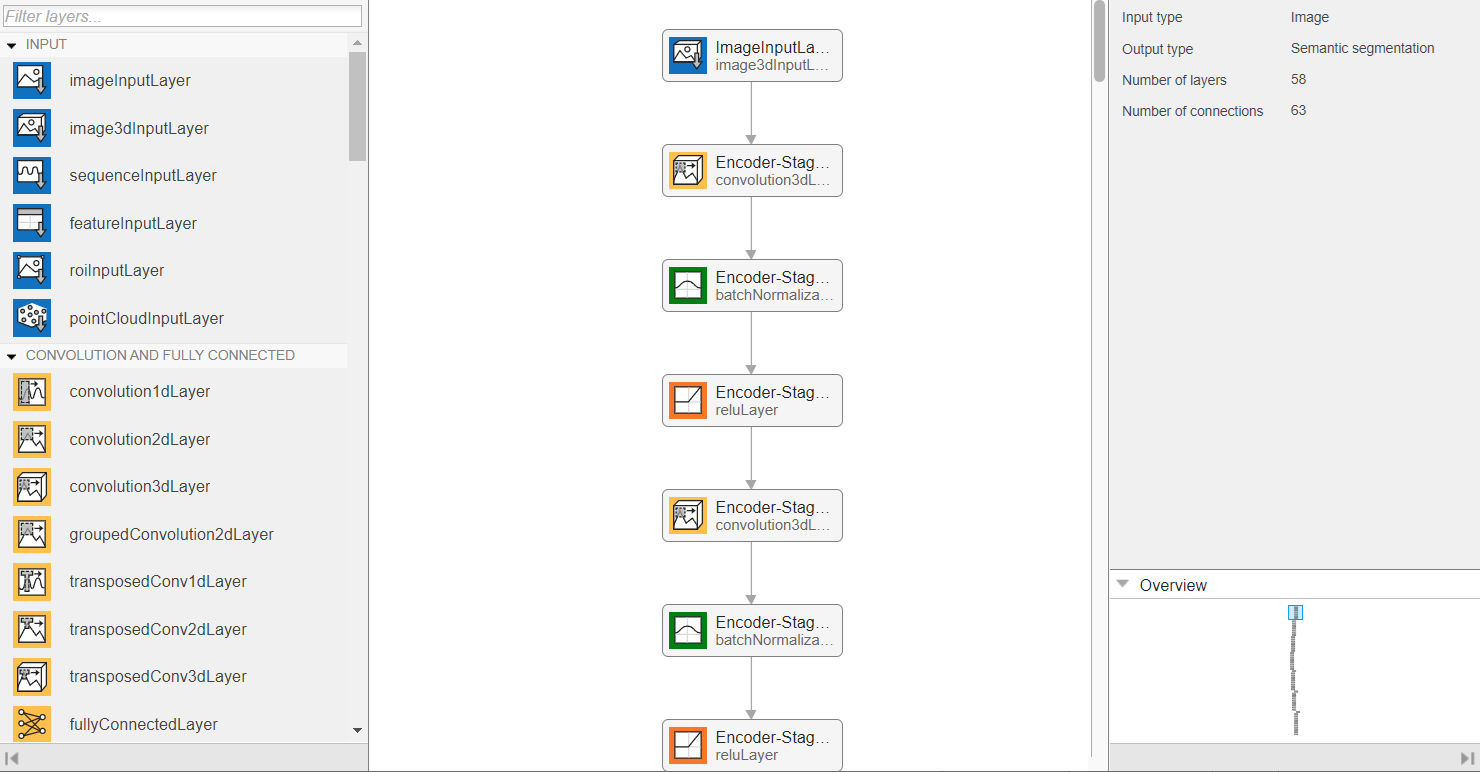

## Train 3-D U-Net

### Specify Training Options

Train the network using the `adam` optimization solver. Specify the hyperparameter settings using the [`trainingOptions`](docid:nnet_ref#bu59f0q) function. The initial learning rate is set to `5e-4`, and gradually decreases over the span of training. You can experiment with the `MiniBatchSize` property based on your GPU memory. To maximize GPU memory utilization, favor large input patches over a large batch size. Note that batch normalization layers are less effective for smaller values of `MiniBatchSize`. Tune the initial learning rate based on the `MiniBatchSize`.

options = trainingOptions("adam", ...
    MaxEpochs=50, ...
    InitialLearnRate=5e-4, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropPeriod=5, ...
    LearnRateDropFactor=0.95, ...
    ValidationData=dsVal, ...
    ValidationFrequency=400, ...
    Plots="training-progress", ...
    Verbose=false, ...
    MiniBatchSize=miniBatchSize);

### Define Loss Function

Define a custom loss function, `generalizedDiceLoss`, that takes predictions `Y` and targets `T` and returns the Generalized Dice loss. The Generalized Dice similarity coefficient measures the overlap between two segmented images. The coefficient is based on Sørensen-Dice similarity, and controls the contribution that each class makes to the similarity by weighting classes by the inverse size of the expected region. For more details, see [`generalizedDice`](docid:vision_ref#mw_479dae53-4172-47df-9a5e-a53a75a4d2e5).

function loss = generalizedDiceLoss(Y,T)
    % Ignore any NaNs introduced to the training data during augmentation
    T(isnan(T)) = 0;
    z = generalizedDice(Y,T);
    % Calculate the mean of the Dice loss across the batch
    loss = 1 - mean(z,"all");
end

### Train Network

By default, the example uses the downloaded pretrained 3-D U-Net network. The pretrained network enables you to perform semantic segmentation and evaluate the segmentation results without waiting for training to complete.

To train the network, set the `doTraining` variable in the following code to `true`. Train the network using the [`trainnet`](docid:nnet_ref#mw_87a4761c-af20-4e6e-9752-e145a8295c97) function. By default, the `trainnet` function uses a GPU if one is available. Training on a GPU requires a Parallel Computing Toolbox™ license and a supported GPU device. For information on supported devices, see [GPU Computing Requirements](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, the `trainnet` function uses the CPU. To specify the execution environment, use the `ExecutionEnvironment` training option.

doTraining = false;
if doTraining
    [trainedNet,info] = trainnet(dsTrain,net,@generalizedDiceLoss,options);
    modelDateTime = string(datetime("now",Format="yyyy-MM-dd-HH-mm-ss"));
    save("trained3DUNet-"+modelDateTime+".mat","trainedNet");
end

## Evaluate 3-D U-Net

Specify the location of the data to use for testing the network. By default, `useFullTestSet` is `false` and the example uses the five sample volumes downloaded in the Load Sample BraTS Data section. If you change the `useFullTestSet` value to `true`, then the example uses 55 of the scans allocated to testing from the full data set.

useFullTestSet = false;
if useFullTestSet
    volLocTest = fullfile(preprocessDataLoc,"imagesTest");
    lblLocTest = fullfile(preprocessDataLoc,"labelsTest");
else
    volLocTest = fullfile(testDir,"imagesTest");
    lblLocTest = fullfile(testDir,"labelsTest");
end

Similar to the training and validation data sets, manage the image data and labels for the testing data set by creating an `imageDatastore` object and `pixelLabelDatastore` object, respectively.

voldsTest = imageDatastore(volLocTest,FileExtensions=".mat", ...
    ReadFcn=@matRead);

pxdsTest = pixelLabelDatastore(lblLocTest,classNames,pixelLabelID, ...
    FileExtensions=".mat",ReadFcn=@matRead);

For each test volume, read the volume as a `blockedImage` object and process each block using the [`apply`](docid:images_ref#mw_d2a929bc-2fd0-45b6-b4ed-0e2671850b23) function. The `apply` function performs the operations specified by the `calculateBlockMetrics` helper function, which is defined at the end of this example. The `calculateBlockMetrics` function performs semantic segmentation of each block, and calculates the confusion matrix between the predicted and ground truth labels.

imageIdx = 1;
datasetConfMat = table;

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU.
* Processed 5 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU
    ______________    ____________    _______    ___________

       0.99902          0.97292       0.95915      0.99807  



while hasdata(voldsTest)


ans =     0.9676
    0.9521
    0.9568
    0.9537
    0.9635


    % Read volume and label data
    vol = read(voldsTest);
    volLabels = read(pxdsTest);

    % Create blockedImage for volume and label data
    testVolume = blockedImage(vol);
    testLabels = blockedImage(volLabels{1});

    % Calculate block metrics
    blockConfMatOneImage = apply(testVolume, ...
        @(block,labeledBlock) ...
            calculateBlockMetrics(block,labeledBlock,trainedNet,classNames), ...
        ExtraImages=testLabels, ...
        PadPartialBlocks=true, ...
        BlockSize=blockSize, ...
        BorderSize=borderSize);

    % Read all the block results of an image and update the image number
    blockConfMatOneImageDS = blockedImageDatastore(blockConfMatOneImage);
    blockConfMat = readall(blockConfMatOneImageDS);
    blockConfMat = struct2table([blockConfMat{:}]);
    blockConfMat.ImageNumber = imageIdx.*ones(height(blockConfMat),1);
    datasetConfMat = [datasetConfMat; blockConfMat];

    imageIdx = imageIdx + 1;
end

Evaluate the data set metrics and block metrics for the segmentation using the [`evaluateSemanticSegmentation`](docid:vision_ref#mw_ec14c36c-b93d-4fde-8512-ea7d51651b89) function.

[metrics,blockMetrics] = evaluateSemanticSegmentation( ...
    datasetConfMat,classNames,Metrics="all");

Display the Jaccard score calculated for each image.

metrics.ImageMetrics.MeanIoU

## Supporting Function

The `calculateBlockMetrics` helper function performs semantic segmentation of a block, and calculates the confusion matrix between the predicted and ground truth labels. The function returns a structure with fields containing the confusion matrix and metadata about the block. You can use the structure with the `evaluateSemanticSegmentation` function to calculate metrics and aggregate block-based results.

function blockMetrics = calculateBlockMetrics(bstruct,gtBlockLabels,net,classNames)

% Segment block
predBlockLabels = semanticseg(bstruct.Data,net,Classes=classNames);

% Trim away border region from gtBlockLabels 
blockStart = bstruct.BorderSize + 1;
blockEnd = blockStart + bstruct.BlockSize - 1;
gtBlockLabels = gtBlockLabels( ...
    blockStart(1):blockEnd(1), ...
    blockStart(2):blockEnd(2), ...
    blockStart(3):blockEnd(3));

% Evaluate segmentation results against ground truth
confusionMat = segmentationConfusionMatrix(predBlockLabels,gtBlockLabels);

% blockMetrics is a struct with confusion matrices, image number,
% and block information 
blockMetrics.ConfusionMatrix = confusionMat;
blockMetrics.ImageNumber = bstruct.ImageNumber;
blockInfo.Start = bstruct.Start;
blockInfo.End = bstruct.End;
blockMetrics.BlockInfo = blockInfo;

end

## References

[1] Çiçek, Özgün, Ahmed Abdulkadir, Soeren S. Lienkamp, Thomas Brox, and Olaf Ronneberger. “3D U-Net: Learning Dense Volumetric Segmentation from Sparse Annotation.” In *Medical Image Computing and Computer-Assisted Intervention – MICCAI 2016*, edited by Sebastien Ourselin, Leo Joskowicz, Mert R. Sabuncu, Gozde Unal, and William Wells, 9901:424–32. Cham: Springer International Publishing, 2016. [https://doi.org/10.1007/978-3-319-46723-8_49](https://doi.org/10.1007/978-3-319-46723-8_49).

[2] Isensee, Fabian, Philipp Kickingereder, Wolfgang Wick, Martin Bendszus, and Klaus H. Maier-Hein. “Brain Tumor Segmentation and Radiomics Survival Prediction: Contribution to the BRATS 2017 Challenge.” In *Brainlesion: Glioma, Multiple Sclerosis, Stroke and Traumatic Brain Injuries*, edited by Alessandro Crimi, Spyridon Bakas, Hugo Kuijf, Bjoern Menze, and Mauricio Reyes, 10670:287–97. Cham: Springer International Publishing, 2018. [https://doi.org/10.1007/978-3-319-75238-9_25](https://doi.org/10.1007/978-3-319-75238-9_25).

[3] "Brain Tumours". *Medical Segmentation Decathlon.* http://medicaldecathlon.com/ 

The BraTS dataset is provided by Medical Segmentation Decathlon under the [CC-BY-SA 4.0 license.](https://creativecommons.org/licenses/by-sa/4.0/) All warranties and representations are disclaimed; see the license for details. MathWorks® has modified the data set linked in the Load Sample BraTS Data section of this example. The modified sample data set has been cropped to a region containing primarily the brain and tumor, and each channel has been normalized independently by subtracting the mean and dividing by the standard deviation of the cropped brain region.

[4] Sudre, Carole H., Wenqi Li, Tom Vercauteren, Sebastien Ourselin, and M. Jorge Cardoso. “Generalised Dice Overlap as a Deep Learning Loss Function for Highly Unbalanced Segmentations.” In *Deep Learning in Medical Image Analysis and Multimodal Learning for Clinical Decision Support*, edited by M. Jorge Cardoso, Tal Arbel, Gustavo Carneiro, Tanveer Syeda-Mahmood, João Manuel R.S. Tavares, Mehdi Moradi, Andrew Bradley, et al., 10553:240–48. Cham: Springer International Publishing, 2017. [https://doi.org/10.1007/978-3-319-67558-9_28](https://doi.org/10.1007/978-3-319-67558-9_28).

[5] Ronneberger, Olaf, Philipp Fischer, and Thomas Brox. “U-Net: Convolutional Networks for Biomedical Image Segmentation.” In *Medical Image Computing and Computer-Assisted Intervention – MICCAI 2015*, edited by Nassir Navab, Joachim Hornegger, William M. Wells, and Alejandro F. Frangi, 9351:234–41. Cham: Springer International Publishing, 2015. [https://doi.org/10.1007/978-3-319-24574-4_28](https://doi.org/10.1007/978-3-319-24574-4_28).

*Copyright 2019-2024 The MathWorks, Inc.*